%--------------------------------------------------------
% Parameters
%--------------------------------------------------------
a1 = 1.2272; %[cm2] Area of outlet pipe 1
a2 = 1.2272;
a3 = 1.2272;
a4 = 1.2272;

A1 = 380.1327; %[cm2] Cross sectional area of tank 1
A2 = 380.1327; %[cm2] Cross sectional area of tank 2
A3 = 380.1327; %[cm2] Cross sectional area of tank 3
A4 = 380.1327; %[cm2] Cross sectional area of tank 4

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981;       %[cm/s2] The acceleration of gravity
rho = 1.00;    %[g/cm3] Density of water

p = [a1;a2;a3;a4; A1;A2;A3;A4; gamma1; gamma2; g; rho];


%-------------------------------------------------------
% System equations
%-------------------------------------------------------
function xdot = FourTankSystem(t,x,u,p)
% FOURTANKSYSTEM Model dx/dt = f(t,x,u,p) for 4-tank system

 m = x; % Mass of liquid in each tank [g]
 F = u; % Flow rates in pumps [cm3/s]
 a = p(1:4,1); % Pipe cross sectional areas [cm2]
 A = p(5:8,1); % Tank cross sectional areas [cm2]
 gamma = p(9:10,1); % Valve positions [-]
 g = p(11,1);   % Acceleration of gravity [cm/s2]
 rho = p(12,1); % Density of water [g/cm3]


 % Inflows
 qin = zeros(4,1);
 qin(1,1) = gamma(1)*F(1);     % Valve 1 to tank 1 [cm3/s]
 qin(2,1) = gamma(2)*F(2);     % Valve 2 to tank 2 [cm3/s]
 qin(3,1) = (1-gamma(2))*F(2); % Valve 2 to tank 3 [cm3/s]
 qin(4,1) = (1-gamma(1))*F(1); % Valve 1 to tank 4 [cm3/s]
 
 % % Outflows
 h = m./(rho*A);         % Liquid level in each tank [cm]
 qout = a.*sqrt(2*g*h);  % Outflow from each tank [cm3/s]

 % Differential equations, mass balances
 xdot = zeros(4,1);
 xdot(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Tank 1
 xdot(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Tank 2
 xdot(3,1) = rho*(qin(3,1)-qout(3,1));  % Tank 3
 xdot(4,1) = rho*(qin(4,1)-qout(4,1));  % Tank 4
end

%-------------------------------------------------------
% Simulation scenario
%-------------------------------------------------------
t0 = 0.0;   % [s] Initial time
tf = 20*60; % [s] Final time
m10 = 0.0;  % [g] Liquid mass in tank 1 at time t0
m20 = 0.0;
m30 = 0.0;
m40 = 0.0;
F1 = 200;   % [cm3/s] Flow rate from pump 1
F2 = 200;

x0 = [m10; m20; m30; m40];
u = [F1; F2];

%-------------------------------------------------------
% Compute the solution / Simulate
%-------------------------------------------------------

% Solve the system of differential equations
[T,X] = ode15s(@FourTankSystem,[t0 tf],x0,[],u,p);
 
% help variables
[nT,nX] = size(X);
a = p(1:4,1)';
A = p(5:8,1)';

% Compute the measured variables
H = zeros(nT,nX);
for i=1:nT
    H(i,:) = X(i,:)./(rho*A);
end  

% Compute the flows out of each tank
Qout = zeros(nT,nX);
for i=1:nT
    Qout(i,:) = a.*sqrt(2*g*H(i,:));
end

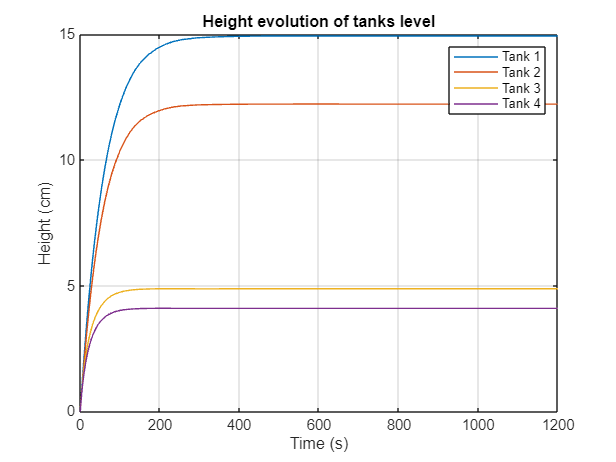

plot(T, H)
xlabel('Time (s)');
ylabel('Height (cm)');
title('Height evolution of tanks level');
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4');
grid on;

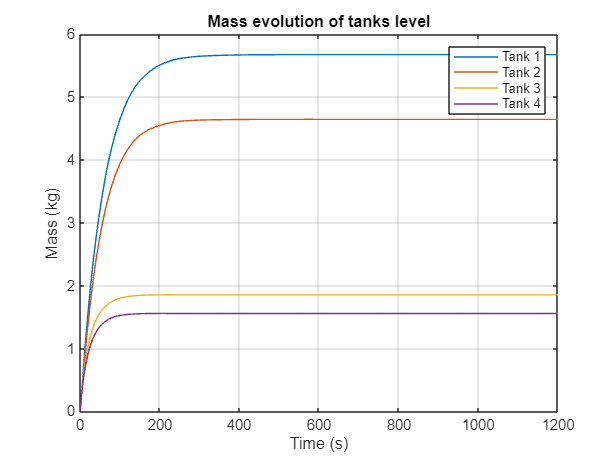


plot(T, X/1000)
xlabel('Time (s)');
ylabel('Mass (kg)');
title('Mass evolution of tanks level');
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4');
grid on;

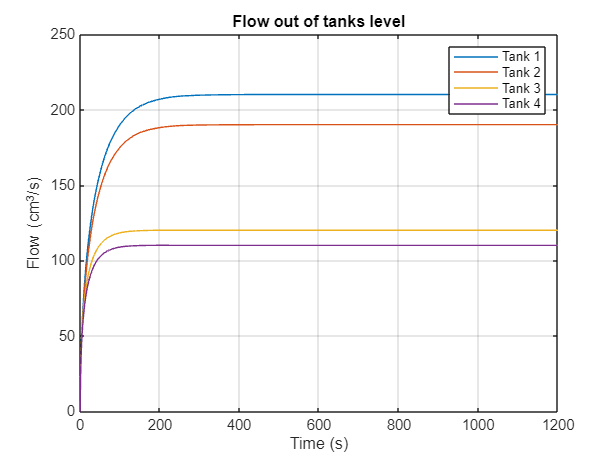


plot(T, Qout)
xlabel('Time (s)');
ylabel('Flow (cm^3/s)');
title('Flow out of tanks level');
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4');
grid on;